# Practica 5. Ecuaciones en Diferiencias

1. Utilice la función impz() de  Matlab para graficar la respuesta al impulso de los sistemas representados por las siguientes ecuaciones en diferencias:

a) $y(n)-\frac{1}{2}y(n-1)=x(n)
$

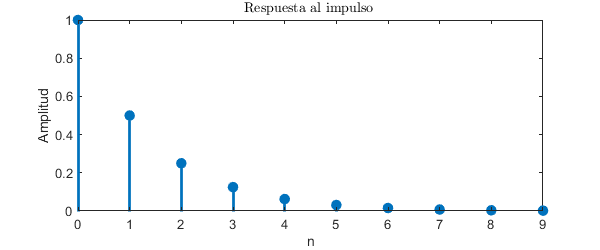

n = 0:10;
figure('Position',[500 400 600 250])
stem(n,impz([1],[1 -1/2],11),'filled','LineWidth',2)
title(' Respuesta al impulso  ','Interpreter','latex')
xlim([0 9])
ylabel('Amplitud')
xlabel('n')

b) $y(n)-\frac{5}{6}y(n-1)+\frac{1}{6}y(n-2)=x(n)
$

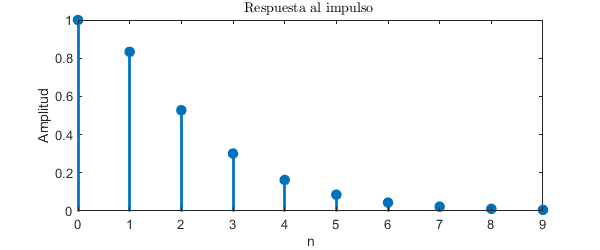

n = 0:10;
figure('Position',[500 400 600 250])
stem(n,impz([1],[1 -5/6 1/6],11),'filled','LineWidth',2)
title(' Respuesta al impulso  ','Interpreter','latex')
xlim([0 9])
ylabel('Amplitud')
xlabel('n')

2.Utilice la función stepz() de  Matlab para graficar la respuesta al escalón de los sistemas representados por las siguientes ecuaciones en diferencias:

a) $y(n)-\frac{1}{2}y(n-1)=x(n)
$

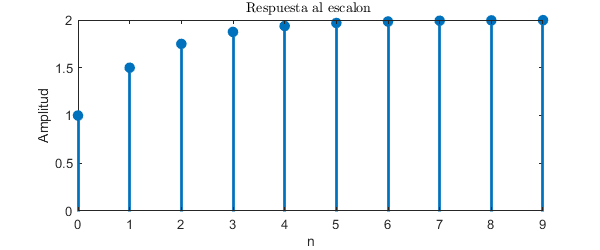

n = 0:10;
figure('Position',[500 400 600 250])
stem(n,stepz(impz([1],[1 -1/2],11)),'filled','LineWidth',2)
title(' Respuesta al escalon  ','Interpreter','latex')
xlim([0 9])
ylabel('Amplitud')
xlabel('n')

b) $y(n)-\frac{5}{6}y(n-1)+\frac{1}{6}y(n-2)=x(n)
$

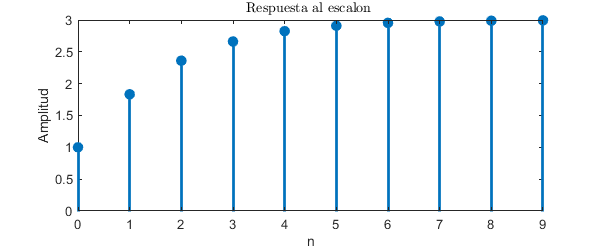

n = 0:10;
figure('Position',[500 400 600 250])
stem(n,stepz(impz([1],[1 -5/6 1/6],11)),'filled','LineWidth',2)
title(' Respuesta al escalon  ','Interpreter','latex')
xlim([0 9])
ylabel('Amplitud')
xlabel('n')

3. Utilice  las funciones filter() y stem() de  Matlab para graficar la respuesta de  los  sistemas representados por las siguientes ecuaciones en diferencias, considerela señal 𝑥(𝑛) indicada y condiciones iniciales iguales a cero:

a) $y(n)-\frac{1}{2}y(n-1)=x(n)
$                    $x(n) = \left(\frac{1}{2}\right)^nu(n)$

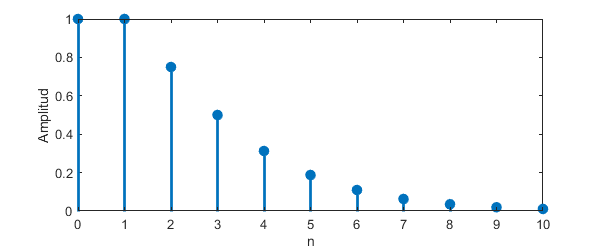

n = 0:10;
figure('Position',[500 400 600 250])
stem(n,filter([1],[1 -1/2],(1/2).^n),'filled','LineWidth',2)
xlim([0 10])
ylabel('Amplitud')
xlabel('n')

b) $y(n)-\frac{5}{6}y(n-1)+\frac{1}{6}y(n-2)=x(n)
$                    $x(n) = \left(\frac{1}{2}\right)^nu(n)$

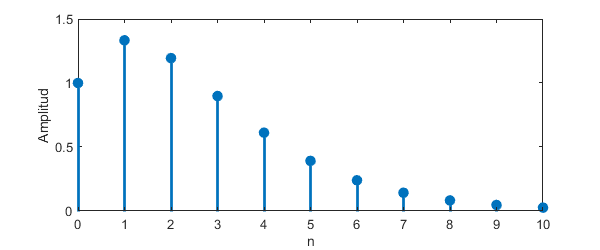

n = 0:10;
figure('Position',[500 400 600 250])
stem(n,filter([1],[1 -5/6 1/6],(1/2).^n),'filled','LineWidth',2)
xlim([0 10])
ylim([0 1.5])
ylabel('Amplitud')
xlabel('n')

4. Utilice las funciones filter(), filtic() y stem() de Matlab para graficar la respuesta de los sistemas representados   por   las siguientes ecuaciones en diferencias, considere la señal 𝑥(𝑛) y condiciones iniciales indicadas:

a) $y(n)-\frac{1}{2}y(n-1)=x(n)
$                    $x(n) = \left(\frac{1}{2}\right)^nu(n)$                    $y(-1) = 1$

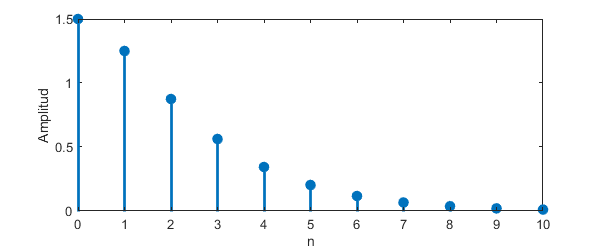

n = 0:10;
figure('Position',[500 400 600 250])
stem(n,filter([1],[1 -1/2],(1/2).^n,filtic([1],[1 -1/2],1)),'filled','LineWidth',2)
xlim([0 10])
ylabel('Amplitud')
xlabel('n')

b) $y(n)-\frac{5}{6}y(n-1)+\frac{1}{6}y(n-2)=x(n)
$                    $x(n) = \left(\frac{1}{2}\right)^nu(n)$                    $y(-1) = 1$        $y(-2) = 0$ 

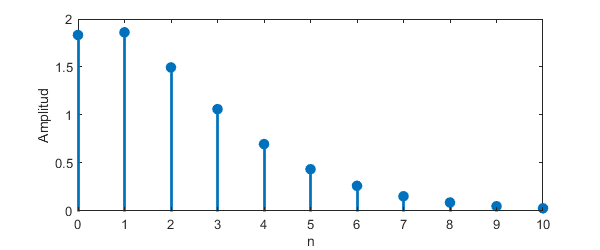

n = 0:10;
figure('Position',[500 400 600 250])
stem(n,filter([1],[1 -5/6 1/6],(1/2).^n,filtic([1],[1 -5/6 1/6],[1 0])),'filled','LineWidth',2)
xlim([0 10])
ylabel('Amplitud')
xlabel('n')

Anexo de Codigo

% Ejercicio 1.a

n = 0:10;

figure('Position',[500 400 600 250])

stem(n,impz([1],[1 -1/2],11),'filled','LineWidth',2)

title(' Respuesta al impulso  ','Interpreter','latex')

xlim([0 9])

ylabel('Amplitud')

xlabel('n')

% Ejercicio 1.b

n = 0:10;

figure('Position',[500 400 600 250])

stem(n,impz([1],[1 -5/6 1/6],11),'filled','LineWidth',2)

title(' Respuesta al impulso  ','Interpreter','latex')

xlim([0 9])

ylabel('Amplitud')

xlabel('n')

% Ejercicio 2.a

n = 0:10;

figure('Position',[500 400 600 250])

stem(n,stepz(impz([1],[1 -1/2],11)),'filled','LineWidth',2)

title(' Respuesta al escalon  ','Interpreter','latex')

xlim([0 9])

ylabel('Amplitud')

xlabel('n')

% Ejercicio 2.b

n = 0:10;

figure('Position',[500 400 600 250])

stem(n,stepz(impz([1],[1 -5/6 1/6],11)),'filled','LineWidth',2)

title(' Respuesta al escalon  ','Interpreter','latex')

xlim([0 9])

ylabel('Amplitud')

xlabel('n')

% Ejercicio 3.a

n = 0:10;

figure('Position',[500 400 600 250])

stem(n,filter([1],[1 -1/2],(1/2).^n),'filled','LineWidth',2)

xlim([0 10])

ylabel('Amplitud')

xlabel('n')

% Ejercicio 3.b

n = 0:10;

figure('Position',[500 400 600 250])

stem(n,filter([1],[1 -5/6 1/6],(1/2).^n),'filled','LineWidth',2)

xlim([0 10])

ylim([0 1.5])

ylabel('Amplitud')

xlabel('n')

%Ejercicio 4.a

n = 0:10;

figure('Position',[500 400 600 250])

stem(n,filter([1],[1 -1/2],(1/2).^n,filtic([1],[1 -1/2],1)),'filled','LineWidth',2)

xlim([0 10])

ylabel('Amplitud')

xlabel('n')

%Ejercicio 4.b

n = 0:10;

figure('Position',[500 400 600 250])

stem(n,filter([1],[1 -5/6 1/6],(1/2).^n,filtic([1],[1 -5/6 1/6],[1 0])),'filled','LineWidth',2)

xlim([0 10])

ylabel('Amplitud')

xlabel('n')